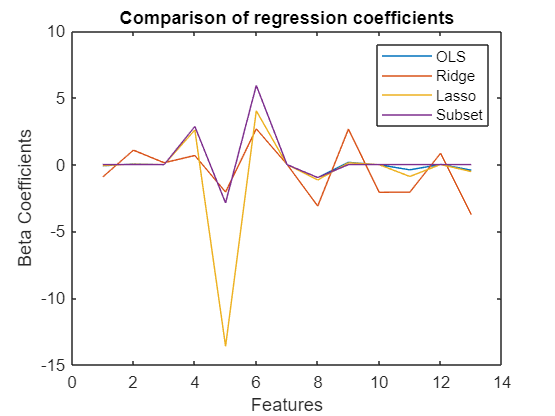

data = load(['C:\Users\param\OneDrive - Clemson University' ...
    '\Desktop\CU\Fall23\Advance Machine Learning\HW1/housing.data']);

x = data(:, 1:13);
y = data(:,14);

% Vanilla Linear Regression
beta_ols = pinv(x' * x) * x' * y;

lambda = 0.1;
% Ridge regression
beta_ridge = ridge(y, x, lambda);

% Lasso regression
[beta_lasso, fitinfo] = lasso(x, y, 'Lambda', lambda, 'intercept', true);

% Subset (Simple implementation using a thresholding on OLS coefficients)
lambda_subset = 0.5;
beta_subset = beta_ols;
beta_subset(abs(beta_ols) < lambda_subset) = 0;

% Plot
figure;
plot(1:13, beta_ols, 'DisplayName', 'OLS');
hold on;
plot(1:13, beta_ridge, 'DisplayName', 'Ridge');
plot(1:13, beta_lasso, 'DisplayName', 'Lasso');
plot(1:13, beta_subset, 'DisplayName', 'Subset');
title('Comparison of regression coefficients');
xlabel('Features');
ylabel('Beta Coefficients');
legend();
hold off;